**LEP 6-3 : Isothermal Semibatch Reactor with Second order Reaction **

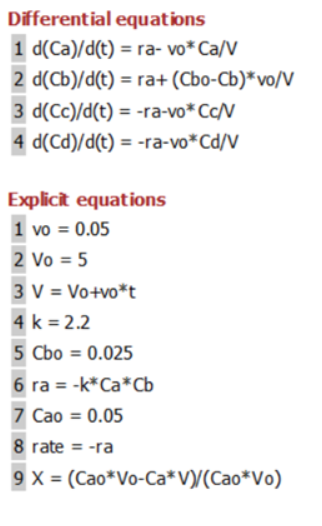

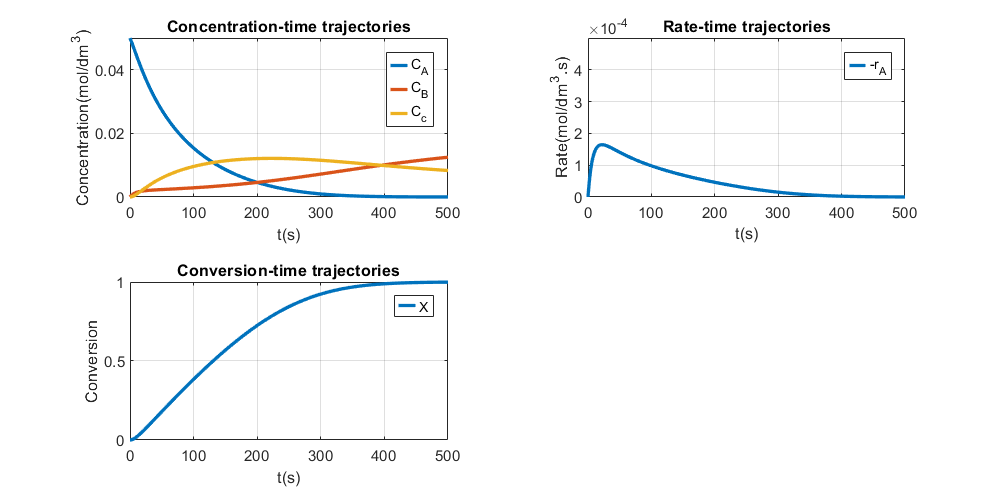

tspan = [0 500]; % Range for the independent variable time 
y0 = [0.05; 0; 0; 0]; % Initial values for the dependent variables i.e. Ca,Cb,Cc,and Cd
vo = 0.05; 
Vo = 5;
k = 2.2; 
Cbo = 0.025; 
[t,y]=ode45(@(t,y)ODEfun(t,y,vo,Vo,k,Cbo),tspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,800,400])
nexttile
plot(t,y(:,1),t,y(:,2),t,y(:,3),'LineWidth',2)
leg=legend('C_A','C_B','C_c');
leg.ItemTokenSize=[10,10];
xlabel('t(s)')
ylabel('Concentration(mol/dm^3)')
title('Concentration-time trajectories')
axis([0 500 0 0.05])
grid on
z=size(y);
Cao = 0.05; 
for i=1 : z(1,1)
ra(i) = 0 - (k * y(i,1) * y(i,2)); 
V(i) = Vo + vo * t(i); 
X(i) = (Cao * Vo - (y(i,1) * V(i))) / (Cao * Vo); 
end
nexttile
plot(t,-ra(1:z(1,1)),'LineWidth',2)
leg=legend('-r_A');
leg.ItemTokenSize=[10,10];
xlabel('t(s)')
ylabel('Rate(mol/dm^3.s)')
title('Rate-time trajectories')
axis([0 500 0 0.0005])
grid on
nexttile
plot(t,X(1:z(1,1)),'LineWidth',2)
leg=legend('X');
leg.ItemTokenSize=[10,10];
xlabel('t(s)')
ylabel('Conversion')
title('Conversion-time trajectories')
axis([0 500 0 1])
grid on

function dYfuncvecdt = ODEfun(t,Yfuncvec,vo,Vo,k,Cbo); 
Ca = Yfuncvec(1); 
Cb = Yfuncvec(2); 
Cc = Yfuncvec(3); 
Cd = Yfuncvec(4); 
% Explicit equations
V = Vo + vo * t; 
ra = 0 - (k * Ca * Cb); 
Cao = 0.05; 
rate = 0 - ra; 
X = (Cao * Vo - (Ca * V)) / (Cao * Vo); 
% Differential equations
dCadt = ra - (vo * Ca / V); 
dCbdt = ra + (Cbo - Cb) * vo / V; 
dCcdt = 0 - ra - (vo * Cc / V); 
dCddt = 0 - ra - (vo * Cd / V); 
dYfuncvecdt = [dCadt; dCbdt; dCcdt; dCddt]; 
end 